load('AnalogData.mat');
rawData = out.AnalogData

rawData =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


Nround = 21;
Nsample = 2001;

% Manipulate matrix
distanceData = rawData(:, 1)

distanceData =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


analogs = rawData(:, 2)

analogs =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


anaData = reshape(analogs, [Nsample, Nround])'

anaData =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    24    26    23    22    23    25    25    22    24    19    26    18    20    28   


% to be used
anaData = cast(anaData, "double");
voltData = anaData .* 3.3 ./ 4096.0

voltData =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0        


meanVoltDataVSRef = ((mean(voltData, 2)/3.3) *100)

meanVoltDataVSRef =          0
         0
         0
    0.5809
    1.7305
    2.9422
    3.9967
    5.1707
    6.2118
    7.2569


measureX = 0 : 5 : 100

measureX =      0     5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100


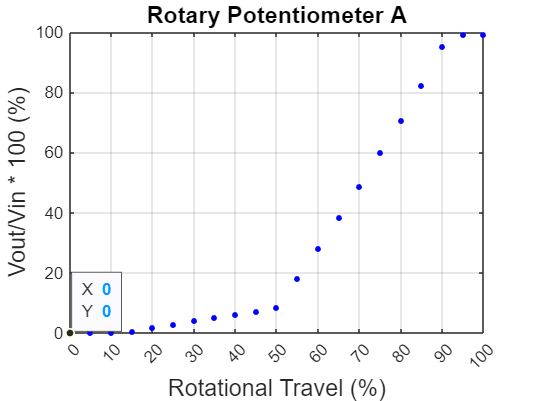

% Plotting
measureGraph = plot(measureX, meanVoltDataVSRef, 'o', 'MarkerSize', 3, 'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b');
% Add on
datatip(measureGraph);
xticks(0:10:100);
xticklabels(0:10:100);
grid on;
title('Rotary Potentiometer A', 'FontSize', 14);
xlabel('Rotational Travel (%)', 'FontSize', 14); 
ylabel('Vout/Vin * 100 (%)', 'FontSize', 14); 

% Load PlotData
load('rotaryA.mat');
load('x.mat');

% Read and plot datasheet
datasheetValue = rotaryA

datasheetValue =     0.0400    0.0600    0.1280    0.4900    1.1100    1.9100    2.9900    4.3600    5.9500    7.7100    9.8900   12.4200   16.3000   21.3400   32.4400   45.7700   60.2700   73.4000   88.6300   99.6000   99.7000


datasheetX = x;

% Calculate Errors
err = 20/100 * datasheetValue

err =     0.0080    0.0120    0.0256    0.0980    0.2220    0.3820    0.5980    0.8720    1.1900    1.5420    1.9780    2.4840    3.2600    4.2680    6.4880    9.1540   12.0540   14.6800   17.7260   19.9200   19.9400


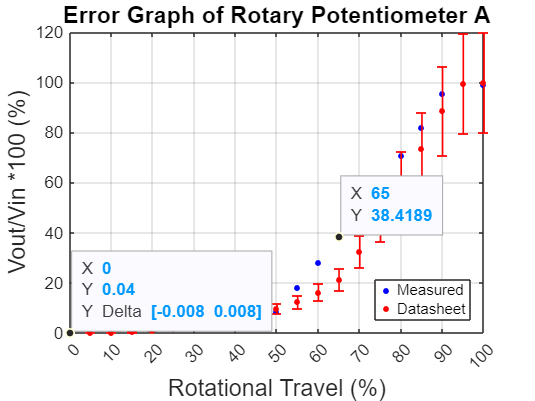

% Plotting Graph
measureGraph;
hold on;
datasheetGraph = plot(datasheetX, datasheetValue, 'o', 'MarkerSize', 3, 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r');
errorGraph = errorbar(measureX, datasheetValue, err, 'or', 'LineWidth', 1, 'MarkerSize', 1, 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r'); 
hold off;
% Add on
datatip(measureGraph);
datatip(datasheetGraph);
datatip(errorGraph);
xticks(0:10:100);
xticklabels(0:10:100);
grid on;
title('Error Graph of Rotary Potentiometer A', 'FontSize', 14);
xlabel('Rotational Travel (%)', 'FontSize', 14); 
ylabel('Vout/Vin *100 (%)', 'FontSize', 14); 
legend('Measured', 'Datasheet', 'Location', 'southeast');